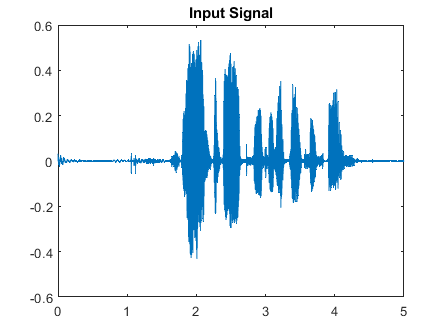

clc, clear, close all;

% 1. Work with the Signal
x = audioread('humanvoice.wav');
x = x(10000:50000); % working with a chunk of signal.
Fs = 8000;
plot(0:1/Fs:1/Fs*(length(x)-1),x); title('Input Signal');

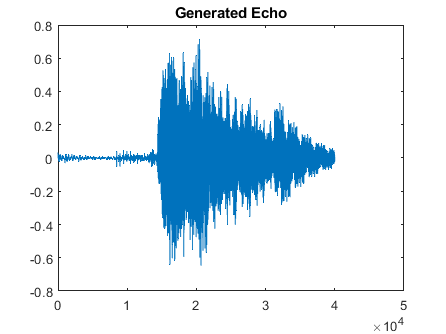

soundsc(x,Fs);
pause(5); % for the later purposes in your code

% echo_delay   = 1.0;                    % in seconds
% echo_delay_s = round(echo_delay*Fs);   % delay in samples
% echo_gain    = 0.8;                    % to control a linear gain of an echo
% h = x + [zeros(echo_delay_s-1, 1); x(echo_delay_s:end)];
% y = conv(x,h);
% soundsc(y);
% pause(10);

% 2. Create the Echo-Corrupted Signal
% Generating echoed sound synthetically.
alpha = 0.8; % |alpha|<1
D = 1000; % set it.
b=1;
a=[ 1 , zeros(1,D) , alpha ];
y = filter(b,a,x);
plot(y); title('Generated Echo')
soundsc(y,Fs)
pause(5)

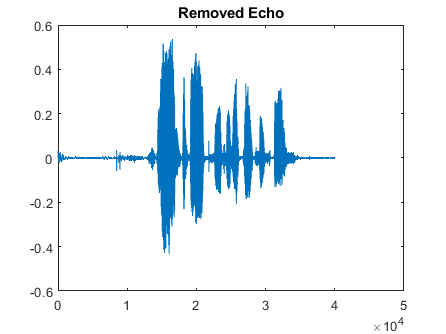


% 3. Remove the Echo
x_hat = filter(a,b,y);
plot(x_hat); title('Removed Echo')

soundsc(x_hat,Fs)


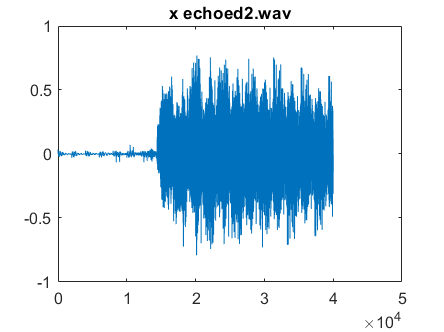

clc, clear, close all; 

% 4. Remove the Echo by Approximating the Echo Model Parameters via Trial-and-Error.
[y, Fs] = audioread('x_echoed2.wav'); 
plot(y); title("x echoed2.wav")

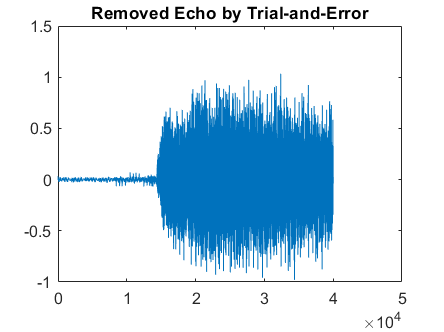

soundsc(y);
pause(5);

alpha = 0.9; % |alpha|<1
% N = Fs*1;
% D = N/Fs; % N/Fs
D = 850;
b=1;
a=[ 1 , zeros(1,D) , alpha ];
x_hat=filter(a,b,y);
plot(x_hat); title("Removed Echo by Trial-and-Error")

soundsc(x_hat);


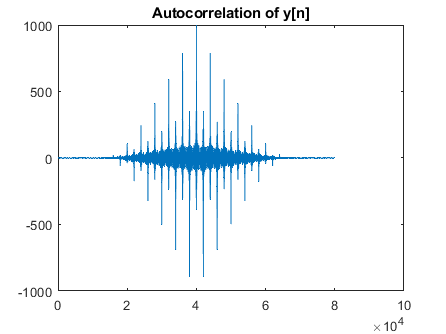

clc, clear, close all;

% 5. Estimating Unknown Echo Parameters Using Autocorrelation.

y = audioread('x_echoed2.wav');
ryy = conv(y,y(end:-1:1));
plot(ryy); title("Autocorrelation of y[n]");